# EchoServer Live Script 3 - Mic Calibration

16 Mar 2022

Run EchoServer 3 and connect the Android clients first.

## 0.1 Basic settings

% Ctrl + Enter to run each section

freq = [14240.625, 14700.   , 15159.375, 15618.75 , 16078.125, 16537.5  ,...
        16996.875, 17456.25 , 17915.625, 18375.   , 18834.375, 19293.75];
fs = 44100;

% high pass filter
fc = 10000;
[b,a] = butter(5, fc/(fs/2), 'high');

% device id
mi6 = 1;
motoz = 2;
pixel4 = 3;

## 0.2 Set up all devices

#### Chirp 2: step tones

sig_len = 41*12;
chirp = zeros(1, sig_len);

for i = 1:sig_len
    j = ceil(i/41);

[I] Current device: 2 (Moto Z).


    phase = 2 * pi * freq(j) * i / fs;
    chirp(i) = weight * sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

#### Chirp 4: multiple tones

% amplitude = 1.0;
% 
% sig_len = 500;
% chirp = zeros(1, sig_len);
% i = 1:sig_len;
% for j = 1:length(freq)

[I] Current device: 3 (Pixel 4).


[I] Current device: 1 (Mi 6).


%     phase = 2 * pi * freq(j) * i ./ fs;
%     chirp = chirp + amplitude * sin(phase);
% end
% chirp = chirp ./ max(abs(chirp));
% 
% % padding zero to 4000
% chirp = [chirp, zeros(1, 4000-sig_len)];
% 
% sig_str = sprintf('%f,', chirp);
% sig_str = sig_str(1:end-1);

#### Send chirp to device 1: Mi 6

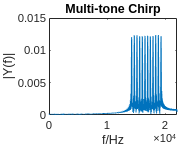

ans =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


device = mi6;
disp("[I] Current device: 1 (Mi 6).")
writeline(server{device}, sig_str)
pause(2)

#### Send chirp to device 2: Moto Z

device = motoz;
disp("[I] Current device: 2 (Moto Z).")
writeline(server{device}, sig_str)
pause(2)

#### Send chirp to device 3: Pixel 4

device = pixel4;
disp("[I] Current device: 3 (Pixel 4).")
writeline(server{device}, sig_str)
pause(2)

## 0.3 Check volume dynamic range

Let both devices play chirp and measure the range of STFT values.

Make sure the chirp played by calibrator cause **echoes** that are loud (and quiet) enough.

device = motoz;

Play

writeline(server{device}, "Play.")   % record
pause(5)
writeline(server{device}, "Play.")   % stop

Plot

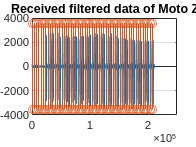

sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Moto Z")
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});

start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

Adjust start point (auto)

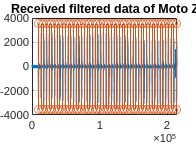

sig_max = max(abs(sig_plot));
start_list_temp = [];
i = 0;
while i < length(sig_plot)
    i = i + 1;
    if sig_plot(i) > sig_max * 0.4
        start_list_temp = [start_list_temp i];
        i = i + 3800;
    end
end

% re-plot
device = motoz;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Moto Z")
hold on
grid on
start_x = [start_list_temp, start_list_temp];
start_l = length(start_list_temp);
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

## STFT spectrogram of chirp (mic of device 2: Moto Z)

Kindly select the chunks:

r = 6 : start_l - 1;

Kindly adjust the duration: 550 ~ 2920-1

ss_spec_sum = zeros(12, 9);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 2920 - 550 - 1;
    signal_filtered = data_filtered{device}(rr + 550: rr + 2920-1); % Adjust the duration!

    % stft
    [ss, ff, tt] = superstft(signal_filtered);
    ss = abs(ss);
    
%     % plot one of them
%     if i == 20 
%         figure
%         S = ss / max(max(ss));
%         I = mat2gray(S);
%         imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%         xlabel('distance / m'); ylabel('frequency / kHz');
%         % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%         % xlabel('time / ms'); ylabel('frequency / kHz');
%     
%         title("STFT of Signal (Moto Z, 550~2919)")
%         set(gca, 'YDir', 'normal');
%         colormap('hot')
%     end
    ss_spec_sum = ss_spec_sum + ss; % for spectrum wise average
    stft_all_2 = [stft_all_2 ss]; % add 48 points to each freq, do this N times
end
ss_spec_avg = ss_spec_sum ./ length(r); % spectrum wise average
stft_avg_2 = [stft_avg_2 ss_spec_avg]; % add 48 points to each freq

% % plot averaged spec
% figure
% S = ss_spec_avg / max(max(ss_spec_avg));
% I = mat2gray(S);
% imagesc(tt * 170, ff / 1000, I); % distance as x-axis
% xlabel('distance / m'); ylabel('frequency / kHz');
% % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% % xlabel('time / ms'); ylabel('frequency / kHz');
% 
% title("Averaged spectrogram of filtered chirp (Moto Z, 550~2919)")
% set(gca, 'YDir', 'normal');
% colormap('hot')

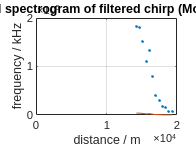

writeline(server{motoz}, "Play.")   % record

writeline(server{pixel4}, "Play.")  % record
writeline(server{mi6}, "Play.")     % play
pause(5)
writeline(server{mi6}, "Play.")     % stop
writeline(server{motoz}, "Play.")
writeline(server{pixel4}, "Play.")

## 0.2 Mute source and target speaker

You can also mute calibrator to reset it.

#### Chirp 0: mute

sig_str = sprintf('%f,', zeros(1,4000));
sig_str = sig_str(1:end-1);

#### Send chirp to device 1: Mi 6

device = mi6;
disp("[I] Current device: 1 (Mi 6).")
writeline(server{device}, sig_str)
pause(2)

#### Send chirp to device 2: Moto Z

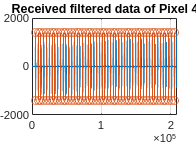

device = motoz;
disp("[I] Current device: 2 (Moto Z).")
writeline(server{device}, sig_str)

pause(2)

#### Send chirp to device 3: Pixel 4

device = pixel4;
disp("[I] Current device: 3 (Pixel 4).")
writeline(server{device}, sig_str)
pause(2)

## 0.3 Initialize amplitude weight and data-pair matrix

All 0.x sections should run only once.

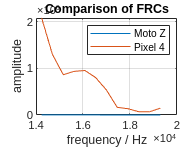

weight = 1;

stft_all_2 = []; % 12x(Nx48x50)

stft_avg_2 = []; % 12x(48x50)

stft_all_3 = []; % 12x(Nx48x50)
stft_avg_3 = []; % 12x(48x50)

#### Check the chirp (optional)

% superfft(chirp,length(chirp),44100,'single','plot','Multi-tone Chirp')

## 1.2 Play on calibrator speaker, record on other 2 mics

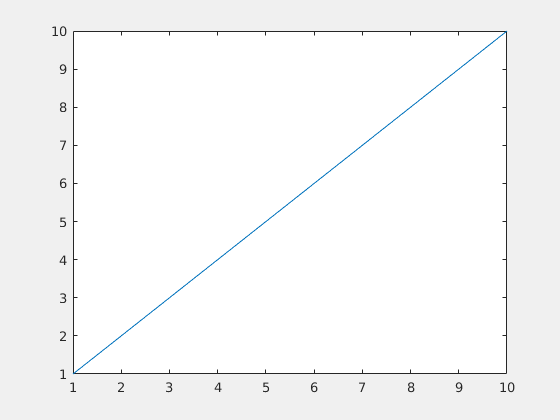

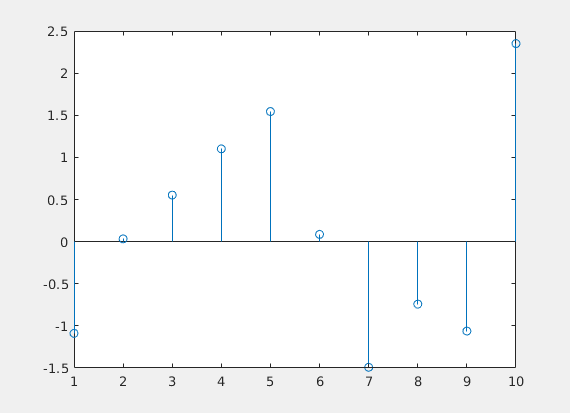

writeline(server{motoz}, "Play.")   % record

writeline(server{pixel4}, "Play.")  % record
writeline(server{mi6}, "Play.")     % play
pause(5)
writeline(server{mi6}, "Play.")     % stop
writeline(server{motoz}, "Play.")
writeline(server{pixel4}, "Play.")

## 2.1 Plot source mic data

Check on the available chunks.

device = motoz;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Moto Z")
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

## 2.1* Adjust start point (auto)

Usually start_list{idx} will have some problem. Find start point again with start_list_temp.

sig_max = max(abs(sig_plot));
start_list_temp = [];
i = 0;
while i < length(sig_plot)
    i = i + 1;
    if sig_plot(i) > sig_max * 0.4
        start_list_temp = [start_list_temp i];
        i = i + 3800;
    end
end

% re-plot
device = motoz;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Moto Z")
hold on
grid on
start_x = [start_list_temp, start_list_temp];
start_l = length(start_list_temp);
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

Manually adjust:

## 2.2 STFT spectrogram of chirp (mic of device 2: Moto Z)

If there are 50 volume levels:

Plan A: N*48*50 pairs of samples on each frequency.

Plan B: 48*50 pairs of samples on each frequency.

Kindly select the chunks:

r = 6 : start_l - 1;

Kindly adjust the duration: 550 ~ 2920-1

device = motoz;
ss_spec_sum = zeros(12, 9);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 2920 - 550 - 1;
    signal_filtered = data_filtered{device}(rr + 550: rr + 2920-1); % Adjust the duration!

    % stft
    [ss, ff, tt] = superstft(signal_filtered);
    ss = abs(ss);
    
%     % plot one of them
%     if i == 20 
%         figure
%         S = ss / max(max(ss));
%         I = mat2gray(S);
%         imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%         xlabel('distance / m'); ylabel('frequency / kHz');
%         % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%         % xlabel('time / ms'); ylabel('frequency / kHz');
%     
%         title("STFT of Signal (Moto Z, 550~2919)")
%         set(gca, 'YDir', 'normal');
%         colormap('hot')
%     end
    ss_spec_sum = ss_spec_sum + ss; % for spectrum wise average
    stft_all_2 = [stft_all_2 ss]; % add 48 points to each freq, do this N times
end
ss_spec_avg = ss_spec_sum ./ length(r); % spectrum wise average
stft_avg_2 = [stft_avg_2 ss_spec_avg]; % add 48 points to each freq

% % plot averaged spec
% figure
% S = ss_spec_avg / max(max(ss_spec_avg));
% I = mat2gray(S);
% imagesc(tt * 170, ff / 1000, I); % distance as x-axis
% xlabel('distance / m'); ylabel('frequency / kHz');
% % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% % xlabel('time / ms'); ylabel('frequency / kHz');
% 
% title("Averaged spectrogram of filtered chirp (Moto Z, 550~2919)")
% set(gca, 'YDir', 'normal');
% colormap('hot')

## 3.1 Plot target mic data

Check on the available chunks

device = pixel4;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Pixel 4")
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

## 3.1* Adjust start point (auto)

Usually start_list{idx} will have some problem. Find start point again with start_list_temp.

sig_max = max(abs(sig_plot));
start_list_temp = [];
i = 0;
while i < length(sig_plot)
    i = i + 1;
    if sig_plot(i) > sig_max * 0.4
        start_list_temp = [start_list_temp i];
        i = i + 3800;
    end
end

% re-plot
device = pixel4;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Pixel 4")
hold on
grid on
start_x = [start_list_temp, start_list_temp];
start_l = length(start_list_temp);
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

Manually adjust:

## 3.2 STFT spectrogram of chirp (mic of device 3: Pixel 4)

If there are 50 volume levels:

Plan A: N*48*50 pairs of samples on each frequency.

Plan B: 48*50 pairs of samples on each frequency.

Kindly select the chunks:

r = 6 : start_l - 1;

Kindly adjust the duration: 550 ~ 2920-1

device = pixel4;
ss_spec_sum = zeros(12, 9);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 2920 - 550 - 1;
    signal_filtered = data_filtered{device}(rr + 550: rr + 2920-1); % Adjust the duration!

    % stft
    [ss, ff, tt] = superstft(signal_filtered);
    ss = abs(ss);
    
%     % plot one of them
%     if i == 20 
%         figure
%         S = ss / max(max(ss));
%         I = mat2gray(S);
%         imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%         xlabel('distance / m'); ylabel('frequency / kHz');
%         % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%         % xlabel('time / ms'); ylabel('frequency / kHz');
%     
%         title("STFT of Signal (Pixel 4, 550~2919)")
%         set(gca, 'YDir', 'normal');
%         colormap('hot')
%     end
    ss_spec_sum = ss_spec_sum + ss; % for spectrum wise average
    stft_all_3 = [stft_all_3 ss]; % add 48 points to each freq, do this N times
end
ss_spec_avg = ss_spec_sum ./ length(r); % spectrum wise average
stft_avg_3 = [stft_avg_3 ss_spec_avg]; % add 48 points to each freq

% % plot averaged spec
% figure
% S = ss_spec_avg / max(max(ss_spec_avg));
% I = mat2gray(S);
% imagesc(tt * 170, ff / 1000, I); % distance as x-axis
% xlabel('distance / m'); ylabel('frequency / kHz');
% % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% % xlabel('time / ms'); ylabel('frequency / kHz');
% 
% title("Averaged spectrogram of filtered chirp (Pixel 4, 550~2919)")
% set(gca, 'YDir', 'normal');
% colormap('hot')

## 4 Compare 2 and 3 under 12 freq

figure
for i = 1:12
    subplot(2, 6, i)
    plot(stft_all_2, stft_all_3, '.') % should add N*48 dots each time
    title("All STFT value pairs up to now")
end
set(gcf,'Visible','on')
figure
for i = 1:12
    subplot(2, 6, i)
    plot(stft_avg_2, stft_avg_3, '.') % should add 48 dots each time
    title("All averaged STFT value pairs up to now")
end
set(gcf,'Visible','on')

## STFT

function [ss, ff, tt] = superstft(signal_filtered)
    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f-1, :); % end is included in MATLAB
end